per = 0

min_point1 = 18

min_point2 = 19

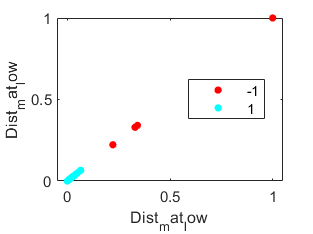

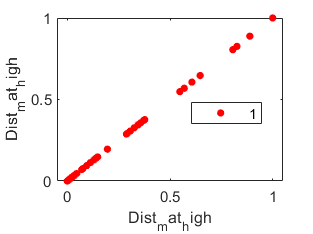

per = 0

min_point1 = 18

min_point2 = 19

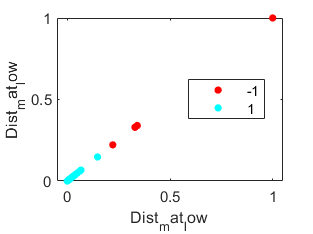

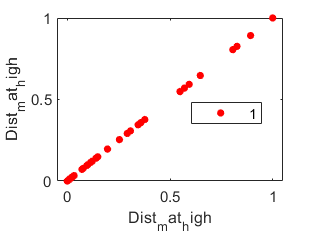

per = 0

min_point1 = 18

min_point2 = 19

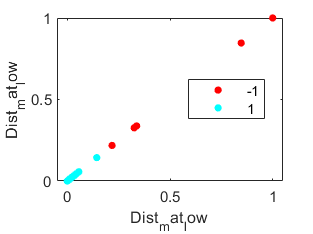

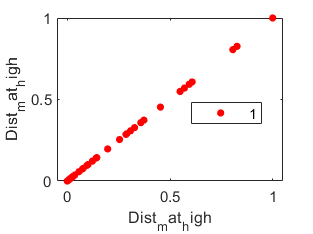

per = 0

min_point1 = 18

min_point2 = 19

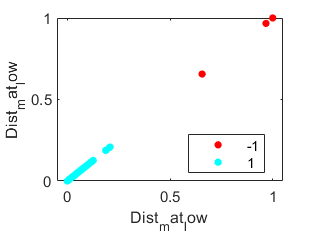

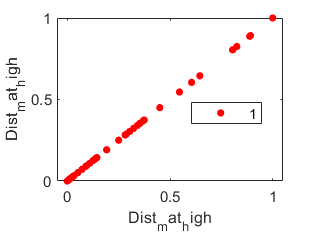

per = 0

min_point1 = 18

min_point2 = 19

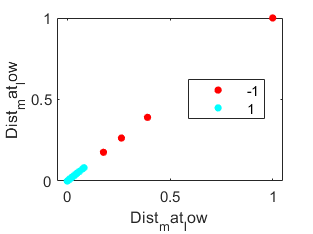

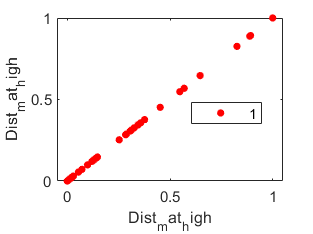

per = 0

min_point1 = 19

min_point2 = 19

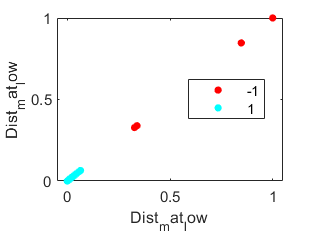

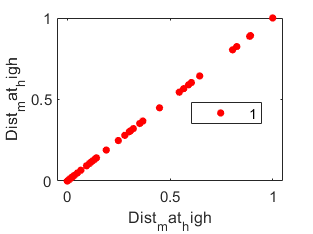

per = 0

min_point1 = 18

min_point2 = 19

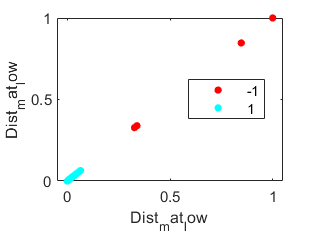

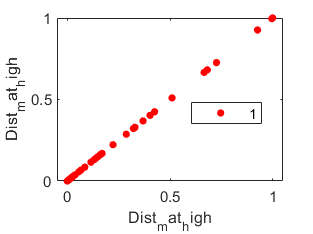

per = 0

min_point1 = 19

min_point2 = 18

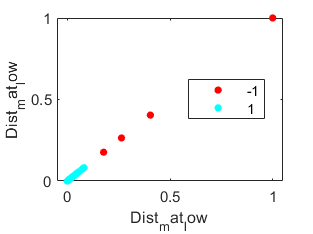

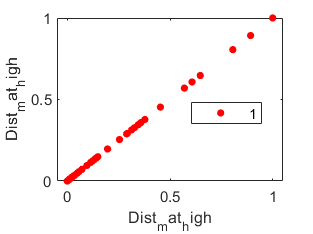

per = 0

min_point1 = 18

min_point2 = 20

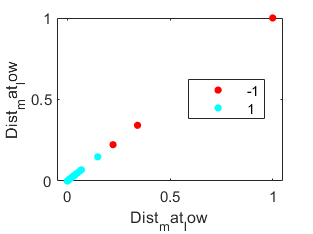

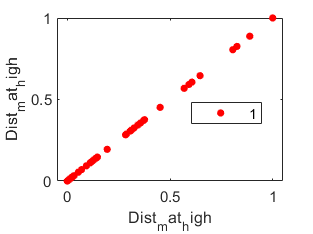

per = 0

min_point1 = 18

min_point2 = 19

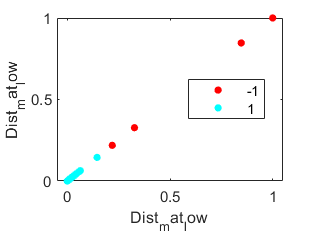

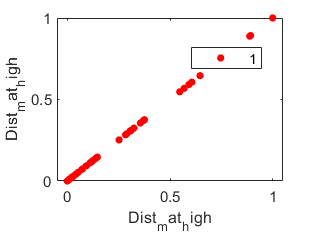

for j = [1,2,3,4,5,6,7,8,9,10]
    figure
    splitfolder=strcat('split',num2str(j));
    per =0%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('weather_train_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        low=File(File(:,10)==1,1:9);
        T_low=low.';

        high=File(File(:,10)==2,1:9);
        T_high=high.';

        folder_l1=strcat('ACE_clust_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        numlow=length(T_low);
        T_low_temp=T_low;

        min_point1= round(5 * length(low)/100)
        clusterer1 = clusterDBSCAN('Epsilon',0.09,'MinNumPoints',min_point1,'EnableDisambiguation',false);

        min_point2= round(5 * length(high)/100)
        clusterer2 = clusterDBSCAN('Epsilon',0.5,'MinNumPoints',min_point2,'EnableDisambiguation',false);


        i = 1;
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering

        Dist_mat_low=[];
        TF_low=[];


        BF_low=l1pca_BF(T_low,i,1,100,100,'');
        for k = 1 : numlow

            A=T_low(:,k);
            Dist_mat_low(k)=norm(A-[BF_low*BF_low.'*A]);
            k;

        end
        Dist_mat_low;
        min_val=min(Dist_mat_low,[],"all");
        max_val=max(Dist_mat_low,[],"all");
        Dist_mat_low= Dist_mat_low -min_val;%]/[max_val-min_val]
        Dist_mat_low=Dist_mat_low /(max_val-min_val);

        cluster_l=clusterer1(Dist_mat_low.').';
        ind_2_l=find(cluster_l==-1);
        ind_1_l=find(cluster_l==1);
        dist_2_l=(Dist_mat_low(:,ind_2_l));
        dist_1_l=(Dist_mat_low(:,ind_1_l));
        mean_2_l= mean(Dist_mat_low(:,ind_2_l));
        mean_1_l= mean(Dist_mat_low(:,ind_1_l));
        figure

        numGroups = length(unique(cluster_l));
        gscatter(Dist_mat_low,Dist_mat_low,cluster_l,hsv(numGroups))

        ind_low=ind_2_l;



        T_low_temp(:,ind_low)=[];


        Final_low=T_low_temp';
        Final_low(:,10)=1;

        numhigh=length(T_high);
        T_high_temp=T_high;


        i = 1;
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering

        Dist_mat_high=[];
        TF_high=[];


        BF_high=l1pca_BF(T_high,i,1,100,100,'');
        for k = 1 : numhigh
            A=T_high(:,k);
            Dist_mat_high(k)=norm(A-[BF_high*BF_high.'*A]);
            k;

        end
        Dist_mat_high;
        min_val=min(Dist_mat_high,[],"all");
        max_val=max(Dist_mat_high,[],"all");
        Dist_mat_high= Dist_mat_high -min_val;%]/[max_val-min_val]
        Dist_mat_high=Dist_mat_high /(max_val-min_val);



        cluster_h=clusterer2(Dist_mat_high.').';
        ind_2_h=find(cluster_h==-1);
        ind_1_h=find(cluster_h==1);
        dist_2_h=(Dist_mat_high(:,ind_2_h));
        dist_1_h=(Dist_mat_high(:,ind_1_h));
        mean_2_h= mean(Dist_mat_high(:,ind_2_h));
        mean_1_h= mean(Dist_mat_high(:,ind_1_h));
        figure
        
        numGroups = length(unique(cluster_h));
        gscatter(Dist_mat_high,Dist_mat_high,cluster_h,hsv(numGroups))

        ind_high=ind_2_h;


        T_high_temp(:,ind_high)=[];

        Final_high=T_high_temp';
        Final_high(:,10)=2;

        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_low.',Final_high.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:10)=  ["air_pressure_9am", "air_temp_9am",	"avg_wind_direction_9am", "avg_wind_speed_9am", "max_wind_direction_9am", "max_wind_speed_9am", "rain_accumulation_9am", "rain_duration_9am","relative_humidity_9am", "relative_humidity_3pm"];
        filel1pca=strcat('weather_misclass_per',num2str(percent),'_ACE_l1pca_',num2str(i),'.csv');
        writetable(L1pca_file,filel1pca);
    end
end